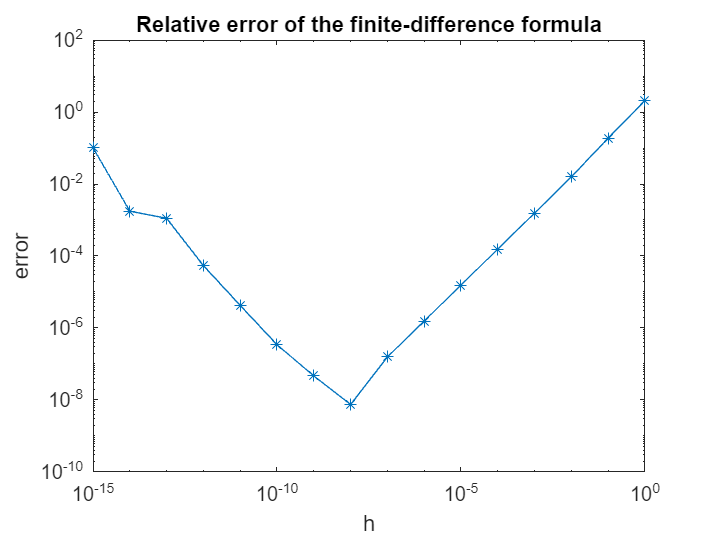

clear
x = 1;

% Define arrays
% Sec_sq and fin_diff not really needed
fin_diff = zeros(16, 1);
sec_sq = zeros(16, 1);
h_values = zeros(16, 1);
error_values = zeros(16, 1);

% Loop through every h value to calculate relative error
for k = 1:16
    % Set up h
    h_values(k) = 10^(-(k-1));
    h = h_values(k);

    % Calculate results of the expressions
    fin_diff(k) = (tan(x+h) - tan(x)) / h;
    sec_sq(k) = (sec(x))^2;

    % Calculate relative error (compare finite difference against sec
    % squared)
    error_values(k) = abs(fin_diff(k) - sec_sq(k)) / abs(sec_sq(k));
end

% Logarithmic plot of the error
loglog(h_values, error_values , '-*');
title('Relative error of the finite-difference formula')
xlabel('h')
ylabel('error')


% When calculating the derivative we take lim h-> 0, so we try to get as
% close to 0 as possible with 10^k. Reasonably the error would be smaller
% as we get closer to 0. But because of computer limits we get
% errors implemented when decreasing so the error gets worse. There is a
% minimum where these errors haven't appeared yet.